## Problem 1

clear; close all;

% Coefficients of the objective function
c = [-2.80; -3.00];  % We multiply by -1 because MATLAB also tries to minimize

% Coefficients of the inequality constraints (left-hand side)
A = [0.11, 0.08; 0.06, 0.03; 0.02, 0.08];

% Constants of the inequality constraints (right-hand side)
b = [600; 300; 330];

% Bounds for variables
lb = [0; 0];
ub = [Inf; Inf];

% Solve the linear programming problem
options = optimoptions('linprog', 'Algorithm', 'dual-simplex');
[x, fval] = linprog(c, A, b, [], [], lb, ub, options);

Optimal solution found.




% Convert back to maximization and display results
max_income = -fval;
x_G = x(1);
x_T = x(2);

fprintf('%.2f L for Growrite and %.2f L for Tomfood.\n', x_G, x_T);

3000.00 L for Growrite and 3375.00 L for Tomfood.


fprintf('The maximum daily income is £%.2f.\n', max_income);

The maximum daily income is £18525.00.


## Problem 2

clear, close all;

% Define the coefficients for the objective function
f = [-35; -20];  % Note the negative signs for a maximization problem

% Define the inequality constraint matrix and vector
A = [23, 11; 4, 4];
b = [176; 51];

% Define the lower bound for the variables
lb = [0; 0];

% Create optimization options
options = optimoptions('linprog', 'Display', 'none');

% Solve the linear programming problem
[x, fval, exitflag, output] = linprog(f, A, b, [], [], lb, [], options);

% Convert the objective function value back to the original maximization problem
optimal_value = -fval;

% Display the results
fprintf('The optimal solution is x = %f, y = %f\n', x(1), x(2));

The optimal solution is x = 2.979167, y = 9.770833


fprintf('The maximum value of the objective function is %f\n', optimal_value);

The maximum value of the objective function is 299.687500


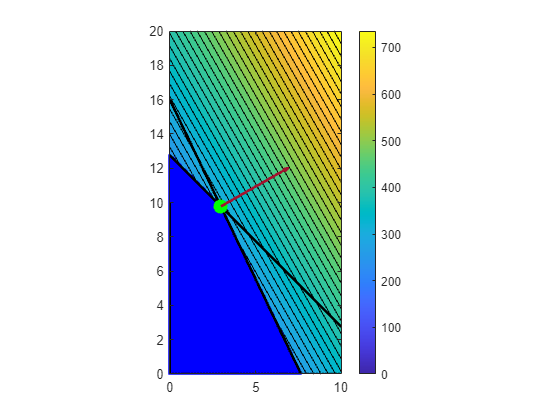


% Create meshgrid for plotting
[X, Y] = meshgrid(linspace(0, 10, 401), linspace(0, 20, 401));

% Define and plot objective function
f = @(x,y) 35*x + 20*y;
contourf(X, Y, f(X,Y), 50); colorbar;
xlim([0, 10]), ylim([0, 20]), axis equal, hold on;

% Determine and plot feasible region using logical indexing
idx1 = 23*X + 11*Y <= 176;  % Constraint 1
idx2 = 4*X + 4*Y <= 51;     % Constraint 2
idx3 = X >= 0;              % Non-negative constraint for x
idx4 = Y >= 0;              % Non-negative constraint for y

% Combine all constraints
idx = idx1 & idx2 & idx3 & idx4;

% Extract coordinates of feasible region
Xf = X(idx); Yf = Y(idx);

% Plot feasible region
plot(Xf, Yf, '.b')

% Plot boundary of feasible region
t = linspace(0, 10, 400);
lw = 'linewidth';
plot(t, (176 - 23*t)/11, '-k', lw, 2)  % Constraint boundary 1
plot(t, (51 - 4*t)/4, '-k', lw, 2)     % Constraint boundary 2
plot(zeros(size(t)), t, '-k', lw, 2)   % Non-negative constraint for x
plot(t, zeros(size(t)), '-k', lw, 2)   % Non-negative constraint for y

% Mark the optimal solution
opt_x = x(1);
opt_y = x(2);
plot(opt_x, opt_y, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');

% Plot normalized gradient
grad_f = [35; 20];
grad_f = 5*grad_f / norm(grad_f);
quiver(opt_x, opt_y, grad_f(1), grad_f(2), 'linewidth', 2)